# Comparing AirwaySkel to Kin's original taper too

% By Ashkan Pakzad on 15th Jan 2020. 
% For comparing AirwaySkel to Kin's original taper tool.

## Include data, set up airwayskel and visualise task

% Hyper Params
CT_name = 'github_demo_raw.nii.gz';
seg_name = 'github_demo_seg.nii.gz';
params = [];

% Load data
meta = niftiinfo(CT_name);
CT = double(niftiread(meta));
    
%Getting the segmented image
S = logical(niftiread(seg_name));

% create airway skeleton class
AS = AirwaySkel(CT, meta, S, params);

## Plot airway tree and distal points

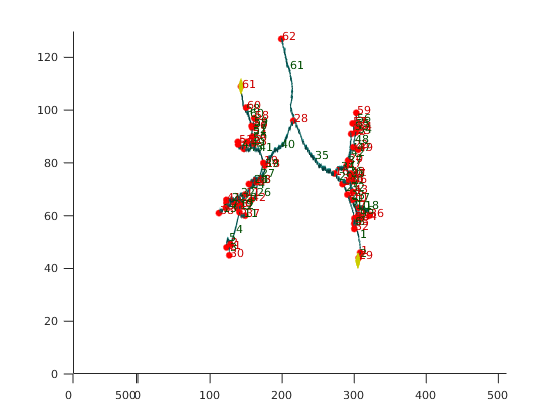

figure
PlotTree(AS)
hold on
D = logical(niftiread('github_demo_dital_point.nii'));
se = strel('sphere',2);
D = imdilate(D, se);
patch(isosurface(D),'FaceColor','none','EdgeColor',[0.8 0.8 0]);

   
disp('Graph result: distal point corresponds to nodes 29 and 61')

Graph result: distal point corresponds to nodes 1 and 58


## Compute Airway taper in AirwaySkel

% Compute Airway slice images
AS = AirwayImageAll(AS)
save('Demo_data_AirwaySkel')

## Execute FWHMesl on all airway segments

% compute Raycasting-FWHMesl of all airways
AS = FindFWHMall(AS)

## Compute path to mirror AT calculation

[AS29_logtaperrate, AS29_cum_arclength, AS29_cum_area, AS29_path] = ConstructTaperPath(AS, 1); 
[AS61_logtaperrate, AS61_cum_arclength, AS61_cum_area, AS61_path] = ConstructTaperPath(AS, 58); 

## Plot AS

% Node 29
figure
area_array = result_sturct.tapering_raw_image.area_results.phyiscal_area;
arclength = result_sturct.tapering_raw_image.arclegth;
tapering_vaule = result_sturct.tapering_raw_image.area_results.tapering;
plot(AS29_cum_arclength,log(AS29_cum_area),'.')
xlabel('Arclength mm')
ylabel('Log Area')
title(['AS 29 Taper = ' num2str(AS29_logtaperrate) ' mm^{-1}'])

## Compute airway taper in AT

% Load the images 
raw_name = 'github_demo_raw.nii';
seg_name = 'github_demo_seg.nii';
distal_name = 'github_demo_dital_point.nii';

% Getting the sturct to process the images
sturct_of_images = Data_into_sturct(raw_name,distal_name,seg_name);

% Getting the reconsturcted image
sturct_of_images = Create_taper_images(sturct_of_images);

% Getting the area and tapering measurments
sturct_of_images = Tapering_and_area(sturct_of_images);

% Saving the file
sturct_of_images.path_of_folders = pwd;
Save_tapering_and_airway_data(sturct_of_images)

## Plot AT

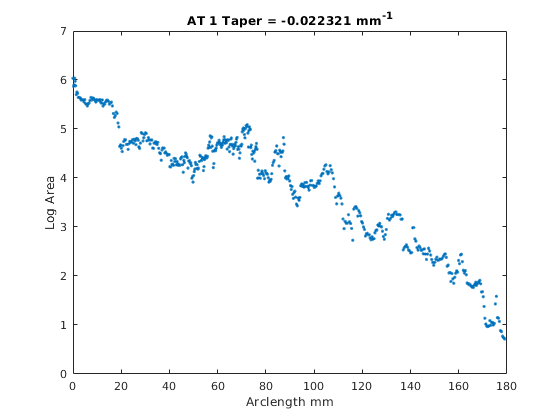


% Node 29
result_sturct = Unpack_loaded_sturct('P_github_demo_raw_A_11170644.mat');
%Ploting the figure
figure
area_array = result_sturct.tapering_raw_image.area_results.phyiscal_area;
arclength = result_sturct.tapering_raw_image.arclegth;
tapering_vaule = result_sturct.tapering_raw_image.area_results.tapering;
plot(arclength,log(area_array),'.')
xlabel('Arclength mm')
ylabel('Log Area')
title(['AT 1 Taper = ' num2str(tapering_vaule) ' mm^{-1}'])

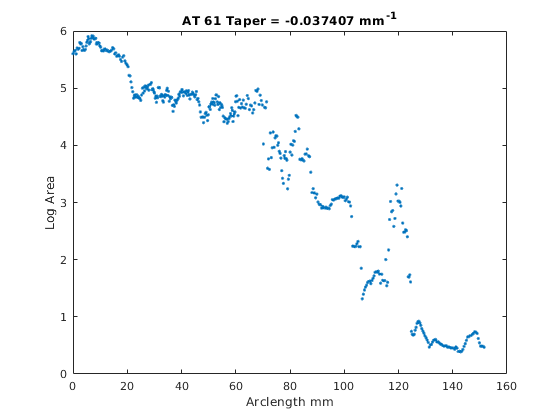


% Node 61
result_sturct = Unpack_loaded_sturct('P_github_demo_raw_A_28451001.mat');
%Ploting the figure
figure
area_array = result_sturct.tapering_raw_image.area_results.phyiscal_area;
arclength = result_sturct.tapering_raw_image.arclegth;
tapering_vaule = result_sturct.tapering_raw_image.area_results.tapering;
plot(arclength,log(area_array),'.')
xlabel('Arclength mm')
ylabel('Log Area')
title(['AT 61 Taper = ' num2str(tapering_vaule) ' mm^{-1}'])